%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 150000

W = 150000


%Airfoil Parameters
Cla = 6

Cla = 6

Tmax = 0.12

Tmax = 0.1200

LocMaxT = 0.3

LocMaxT = 0.3000

PerLamFlow = 0.1

PerLamFlow = 0.1000


%Planform Parameters
b = 81.65; %ft
S = 833.33; %ft^2
TaperRatio = 0.5;
Sexp = 750; %ft^2


Q = 1.01 %For HIGH or MID wing

Q = 1.0100


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
AirDens = DensRat*2.3769*10^-3; %Slug/ft^3
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


AR = 8

AR = 8

Cr = 2*S/(b*(1+TaperRatio))

Cr = 13.6082

Cmac = 2/3*((1+TaperRatio+TaperRatio^2)/(1+TaperRatio))*Cr

Cmac = 10.5841

Ymac = b/6*((1+2*TaperRatio)/(1+TaperRatio))

Ymac = 18.1444


%Calc Lift Curve Slope
beta = sqrt(1-M^2)

beta = 0.8134

eta = Cla/(2*pi)

eta = 0.9549

%CLa = (2*pi*AR*Sexp/S)/(2+sqrt(4+(AR^2*beta^2)/eta^2*(1+(tand(SweepMaxT)^2)/beta^2)))

SweepQuartC = 0:1:40; %Degrees

for x=1:41
    
    SweepMaxT = atand(tand(SweepQuartC(x))-4/AR*((LocMaxT-0.25)*(1-TaperRatio)/(1+TaperRatio)))
    
    %Calc Zero Lift Drag
    Re = AirDens*V*1.688*Cmac/DynVisc;
    ReCut = 38.21*(Cmac/(2.08*10^(-5))); %Smooth Paint surface roughness
    if ReCut < Re 
        Cf = PerLamFlow*1.328/sqrt(Re)+(1-PerLamFlow)*0.455/((log10(ReCut)^2.58)*(1+0.144*(M)^2)^0.65);
    else
        Cf = PerLamFlow*1.328/sqrt(Re)+(1-PerLamFlow)*0.455/((log10(Re)^2.58)*(1+0.144*(M)^2)^0.65);
    end
    FF = (1+0.6*Tmax/LocMaxT+100*Tmax^4)*(1.34*M^(0.18)*(cosd(SweepMaxT)^(0.28))) 
    Swet = (1.977+0.52*Tmax)*Sexp
    CDo = Cf*FF*Q*Swet/S

    %Induced Drag Factor
    Ne = 0; %Num of engines ON TOP of Wing
    TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)
    K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC(x))^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)
    
    CD(x) = CDo + K*(W/(0.5*AirDens*V^2*S))^2
    
end

SweepMaxT = -0.4775

FF = 1.5324

Swet = 1.5296e+03

CDo = 0.0068

TaperFunc = 0.0051

K = 0.0479

CD =     0.0518    0.0425    0.0425    0.0425    0.0425    0.0425    0.0426    0.0426    0.0426    0.0426    0.0426    0.0427    0.0427    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 0.5226

FF = 1.5324

Swet = 1.5296e+03

CDo = 0.0068

TaperFunc = 0.0051

K = 0.0479

CD =     0.0518    0.0518    0.0425    0.0425    0.0425    0.0425    0.0426    0.0426    0.0426    0.0426    0.0426    0.0427    0.0427    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 1.5230

FF = 1.5323

Swet = 1.5296e+03

CDo = 0.0068

TaperFunc = 0.0051

K = 0.0479

CD =     0.0518    0.0518    0.0518    0.0425    0.0425    0.0425    0.0426    0.0426    0.0426    0.0426    0.0426    0.0427    0.0427    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 2.5236

FF = 1.5320

Swet = 1.5296e+03

CDo = 0.0068

TaperFunc = 0.0051

K = 0.0479

CD =     0.0518    0.0518    0.0518    0.0518    0.0425    0.0425    0.0426    0.0426    0.0426    0.0426    0.0426    0.0427    0.0427    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 3.5246

FF = 1.5316

Swet = 1.5296e+03

CDo = 0.0068

TaperFunc = 0.0051

K = 0.0480

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0425    0.0426    0.0426    0.0426    0.0426    0.0426    0.0427    0.0427    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 4.5258

FF = 1.5311

Swet = 1.5296e+03

CDo = 0.0068

TaperFunc = 0.0051

K = 0.0480

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0426    0.0426    0.0426    0.0426    0.0426    0.0427    0.0427    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 5.5274

FF = 1.5304

Swet = 1.5296e+03

CDo = 0.0068

TaperFunc = 0.0051

K = 0.0480

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0426    0.0426    0.0426    0.0426    0.0427    0.0427    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 6.5292

FF = 1.5296

Swet = 1.5296e+03

CDo = 0.0068

TaperFunc = 0.0051

K = 0.0480

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0426    0.0426    0.0426    0.0427    0.0427    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 7.5313

FF = 1.5287

Swet = 1.5296e+03

CDo = 0.0068

TaperFunc = 0.0051

K = 0.0481

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0426    0.0426    0.0427    0.0427    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 8.5336

FF = 1.5277

Swet = 1.5296e+03

CDo = 0.0068

TaperFunc = 0.0051

K = 0.0481

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0426    0.0427    0.0427    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 9.5363

FF = 1.5265

Swet = 1.5296e+03

CDo = 0.0067

TaperFunc = 0.0051

K = 0.0482

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0427    0.0427    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 10.5392

FF = 1.5251

Swet = 1.5296e+03

CDo = 0.0067

TaperFunc = 0.0051

K = 0.0482

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0427    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 11.5424

FF = 1.5237

Swet = 1.5296e+03

CDo = 0.0067

TaperFunc = 0.0051

K = 0.0483

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0427    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 12.5459

FF = 1.5221

Swet = 1.5296e+03

CDo = 0.0067

TaperFunc = 0.0051

K = 0.0483

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0428    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 13.5496

FF = 1.5204

Swet = 1.5296e+03

CDo = 0.0067

TaperFunc = 0.0051

K = 0.0484

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0428    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 14.5536

FF = 1.5185

Swet = 1.5296e+03

CDo = 0.0067

TaperFunc = 0.0051

K = 0.0485

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0429    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 15.5578

FF = 1.5165

Swet = 1.5296e+03

CDo = 0.0067

TaperFunc = 0.0051

K = 0.0485

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0429    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 16.5623

FF = 1.5144

Swet = 1.5296e+03

CDo = 0.0067

TaperFunc = 0.0051

K = 0.0486

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0430    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 17.5671

FF = 1.5121

Swet = 1.5296e+03

CDo = 0.0067

TaperFunc = 0.0051

K = 0.0487

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0430    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 18.5721

FF = 1.5097

Swet = 1.5296e+03

CDo = 0.0067

TaperFunc = 0.0051

K = 0.0488

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0431    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 19.5773

FF = 1.5071

Swet = 1.5296e+03

CDo = 0.0067

TaperFunc = 0.0051

K = 0.0489

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0432    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 20.5827

FF = 1.5044

Swet = 1.5296e+03

CDo = 0.0066

TaperFunc = 0.0051

K = 0.0490

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0432    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 21.5884

FF = 1.5015

Swet = 1.5296e+03

CDo = 0.0066

TaperFunc = 0.0051

K = 0.0491

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0433    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 22.5942

FF = 1.4985

Swet = 1.5296e+03

CDo = 0.0066

TaperFunc = 0.0051

K = 0.0493

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0434    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 23.6003

FF = 1.4954

Swet = 1.5296e+03

CDo = 0.0066

TaperFunc = 0.0051

K = 0.0494

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0435    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 24.6066

FF = 1.4921

Swet = 1.5296e+03

CDo = 0.0066

TaperFunc = 0.0051

K = 0.0495

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0436    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 25.6130

FF = 1.4887

Swet = 1.5296e+03

CDo = 0.0066

TaperFunc = 0.0051

K = 0.0497

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0437    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 26.6197

FF = 1.4851

Swet = 1.5296e+03

CDo = 0.0066

TaperFunc = 0.0051

K = 0.0498

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0438    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 27.6265

FF = 1.4814

Swet = 1.5296e+03

CDo = 0.0065

TaperFunc = 0.0051

K = 0.0500

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0439    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 28.6335

FF = 1.4775

Swet = 1.5296e+03

CDo = 0.0065

TaperFunc = 0.0051

K = 0.0502

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0537    0.0440    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 29.6406

FF = 1.4734

Swet = 1.5296e+03

CDo = 0.0065

TaperFunc = 0.0051

K = 0.0504

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0537    0.0539    0.0442    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 30.6479

FF = 1.4692

Swet = 1.5296e+03

CDo = 0.0065

TaperFunc = 0.0051

K = 0.0506

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0537    0.0539    0.0540    0.0443    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 31.6553

FF = 1.4648

Swet = 1.5296e+03

CDo = 0.0065

TaperFunc = 0.0051

K = 0.0508

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0537    0.0539    0.0540    0.0542    0.0444    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 32.6629

FF = 1.4603

Swet = 1.5296e+03

CDo = 0.0065

TaperFunc = 0.0051

K = 0.0510

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0537    0.0539    0.0540    0.0542    0.0544    0.0446    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 33.6706

FF = 1.4556

Swet = 1.5296e+03

CDo = 0.0064

TaperFunc = 0.0051

K = 0.0513

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0537    0.0539    0.0540    0.0542    0.0544    0.0546    0.0448    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 34.6784

FF = 1.4508

Swet = 1.5296e+03

CDo = 0.0064

TaperFunc = 0.0051

K = 0.0515

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0537    0.0539    0.0540    0.0542    0.0544    0.0546    0.0549    0.0449    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 35.6863

FF = 1.4457

Swet = 1.5296e+03

CDo = 0.0064

TaperFunc = 0.0051

K = 0.0518

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0537    0.0539    0.0540    0.0542    0.0544    0.0546    0.0549    0.0551    0.0451    0.0453    0.0456    0.0458


SweepMaxT = 36.6942

FF = 1.4405

Swet = 1.5296e+03

CDo = 0.0064

TaperFunc = 0.0051

K = 0.0521

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0537    0.0539    0.0540    0.0542    0.0544    0.0546    0.0549    0.0551    0.0553    0.0453    0.0456    0.0458


SweepMaxT = 37.7023

FF = 1.4352

Swet = 1.5296e+03

CDo = 0.0063

TaperFunc = 0.0051

K = 0.0524

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0537    0.0539    0.0540    0.0542    0.0544    0.0546    0.0549    0.0551    0.0553    0.0556    0.0456    0.0458


SweepMaxT = 38.7105

FF = 1.4296

Swet = 1.5296e+03

CDo = 0.0063

TaperFunc = 0.0051

K = 0.0528

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0537    0.0539    0.0540    0.0542    0.0544    0.0546    0.0549    0.0551    0.0553    0.0556    0.0559    0.0458


SweepMaxT = 39.7187

FF = 1.4239

Swet = 1.5296e+03

CDo = 0.0063

TaperFunc = 0.0051

K = 0.0531

CD =     0.0518    0.0518    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0519    0.0520    0.0520    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0524    0.0524    0.0525    0.0526    0.0527    0.0528    0.0529    0.0530    0.0531    0.0533    0.0534    0.0535    0.0537    0.0539    0.0540    0.0542    0.0544    0.0546    0.0549    0.0551    0.0553    0.0556    0.0559    0.0562


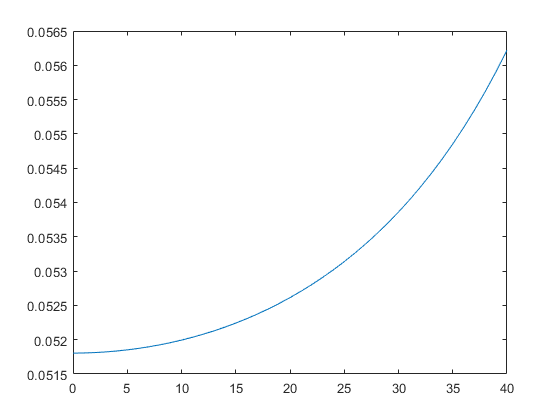


plot(SweepQuartC,CD)